%% Question 2:

A = [ 2 -1  1;
      2  2  2;
     -1 -1  2 ];
b = [-1; 4; -5];

x0      = zeros(3,1);   %initial guess x_0 = 0
maxit   = 25;
x_exact = A\b;          %true solution

% Jacobi iterations
D = diag(diag(A));
R = A - D;              % R = L + U

xJ    = x0;
errJ  = zeros(maxit,1);

for k = 1:maxit
    xJ = D \ (b - R*xJ);                      % Jacobi update
    errJ(k) = norm(xJ - x_exact, inf);       % approximation error
end

% Gauss–Seidel iterations
xGS   = x0;
errGS = zeros(maxit,1);
n     = length(b);

for k = 1:maxit
    x_old = xGS;
    for i = 1:n
        s1 = A(i,1:i-1) * xGS(1:i-1);        % uses newest values
        s2 = A(i,i+1:n) * x_old(i+1:n);      % uses old values
        xGS(i) = (b(i) - s1 - s2) / A(i,i);
    end
    errGS(k) = norm(xGS - x_exact, inf);
end

% Plot: iteration vs approximation error

its = 1:maxit;

figure;
semilogy(its, errJ,  '-o', ...
         its, errGS, '-s');
xlabel('Iteration');
ylabel('Error  ||x^{(k)} - x^*||_\infty');
legend('Jacobi','Gauss-Seidel','Location','best');
grid on;
title('Lab 7 Q2: Iteration vs Approximation Error');

% Computing p(T_GS) and p(T_J):
D = diag(diag(A));
L = tril(A,-1);
U = triu(A,1);

TJ  = -(D \ (L+U));
TGS = -((D+L) \ U);

rhoJ  = max(abs(eig(TJ)))

rhoJ = 1.1180

rhoGS = max(abs(eig(TGS)))

rhoGS = 0.5000


%% Question 3: 
A = [1 2 -2;
     1 1  1;
     2 2  1];

D = diag(diag(A));
L = tril(A,-1);   % strict lower
U = triu(A, 1);   % strict upper

TJ  = -(D \ (L+U));       % Jacobi iteration matrix
TGS = -((D+L) \ U);       % Gauss–Seidel iteration matrix

rhoJ  = max(abs(eig(TJ)))

rhoJ = 1.2329e-05

rhoGS = max(abs(eig(TGS)))

rhoGS = 2

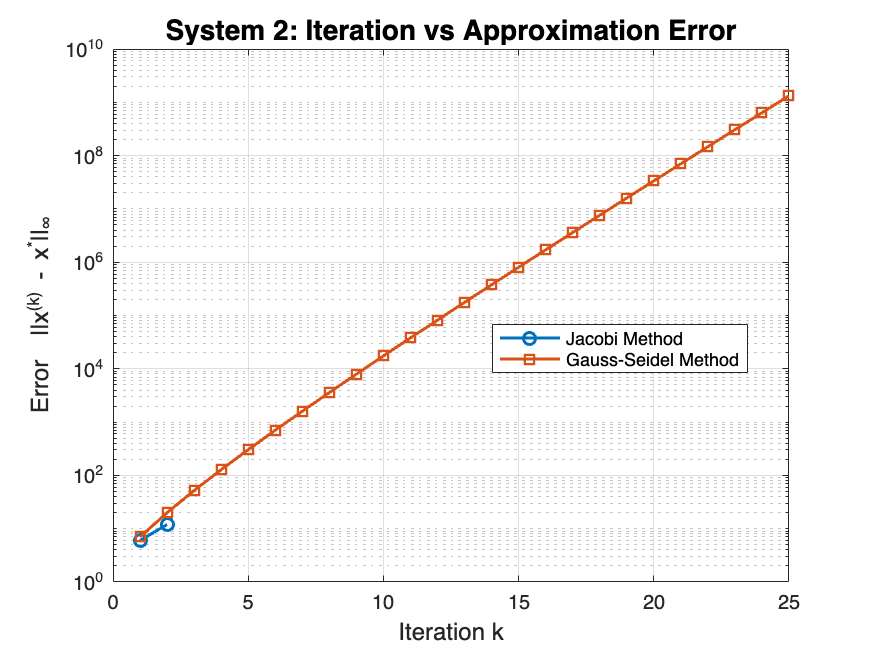



%% Question 4(b):
%% Lab 7 - Iteration vs Approximation Error for Both Systems
clear; clc; close all;

maxit = 25;
x0    = zeros(3,1);

%% =============== System 1 =========================
% [2 -1  1] [x1]   [-1]
% [2  2  2] [x2] = [ 4]
% [-1 -1 2] [x3]   [-5]

A1 = [ 2 -1  1;
       2  2  2;
      -1 -1  2];
b1 = [-1; 4; -5];

x_exact1 = A1\b1;

%Jacobi for System 1
D1 = diag(diag(A1));
R1 = A1 - D1;
xJ1   = x0;
errJ1 = zeros(maxit,1);

for k = 1:maxit
    xJ1 = D1 \ (b1 - R1*xJ1);
    errJ1(k) = norm(xJ1 - x_exact1, inf);
end

%Gauss–Seidel for System 1
xGS1   = x0;
errGS1 = zeros(maxit,1);
n = length(b1);

for k = 1:maxit
    x_old = xGS1;
    for i = 1:n
        s1 = A1(i,1:i-1) * xGS1(1:i-1);
        s2 = A1(i,i+1:n) * x_old(i+1:n);
        xGS1(i) = (b1(i) - s1 - s2) / A1(i,i);
    end
    errGS1(k) = norm(xGS1 - x_exact1, inf);
end

%Plot for System 1
its = 1:maxit;
figure;
semilogy(its, errJ1, '-o', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(its, errGS1, '-s', 'LineWidth', 1.5, 'MarkerSize', 6);
xlabel('Iteration k', 'FontSize', 12);
ylabel('Error  ||x^{(k)} - x^*||_\infty', 'FontSize', 12);
title('System 1: Iteration vs Approximation Error', 'FontSize', 14);
legend('Jacobi Method', 'Gauss-Seidel Method', 'Location', 'best');
grid on;

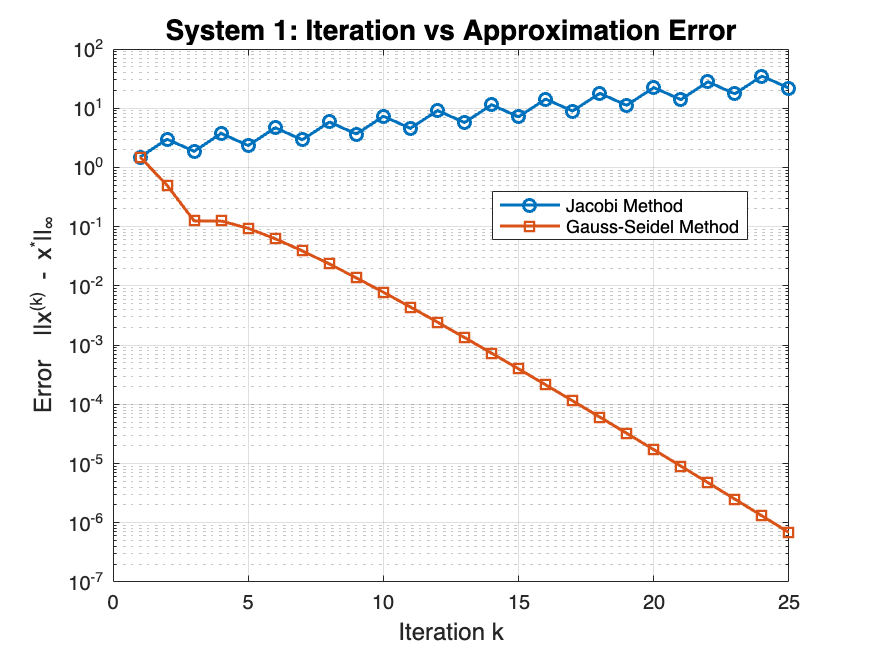


%% =============== System 2 =========================
% [1  2 -2] [x1]   [7]
% [1  1  1] [x2] = [2]
% [2  2  1] [x3]   [5]

A2 = [1 2 -2;
      1 1  1;
      2 2  1];
b2 = [7; 2; 5];

x_exact2 = A2\b2;

%Jacobi for System 2
D2 = diag(diag(A2));
R2 = A2 - D2;
xJ2   = x0;
errJ2 = zeros(maxit,1);

for k = 1:maxit
    xJ2 = D2 \ (b2 - R2*xJ2);
    errJ2(k) = norm(xJ2 - x_exact2, inf);
end

%Gauss–Seidel for System 2
xGS2   = x0;
errGS2 = zeros(maxit,1);

for k = 1:maxit
    x_old = xGS2;
    for i = 1:n
        s1 = A2(i,1:i-1) * xGS2(1:i-1);
        s2 = A2(i,i+1:n) * x_old(i+1:n);
        xGS2(i) = (b2(i) - s1 - s2) / A2(i,i);
    end
    errGS2(k) = norm(xGS2 - x_exact2, inf);
end

%Plot for System 2
figure;
semilogy(its, errJ2, '-o', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(its, errGS2, '-s', 'LineWidth', 1.5, 'MarkerSize', 6);
xlabel('Iteration k', 'FontSize', 12);
ylabel('Error  ||x^{(k)} - x^*||_\infty', 'FontSize', 12);
title('System 2: Iteration vs Approximation Error', 'FontSize', 14);
legend('Jacobi Method', 'Gauss-Seidel Method', 'Location', 'best');
grid on;